clear
close all

%for sce_n_cells_threshold=15
%% Load current data

% load('WinRest')  %period of rest
% load('Tr1b')    %fluo
% load('Cells')       %movie
% load('MovT')        % times of ????   images ???
% load('Speed')      % instantaneous speed
sce_n_cells_threshold = 15;

imaging_sampling_rate=10.32;
synchronous_frames=round(0.2*imaging_sampling_rate,0); %200ms *sampling rate
PathSave='/Users/platel/Desktop/exp/New Folder/';
tic
MovT=transpose(1:12378);  %put real time
speed = readNPY('/Users/platel/Desktop/exp/speed175plane0.npy');
sce=readNPY('/Users/platel/Desktop/exp/sce.npy');
plane0=readNPY('/Users/platel/Desktop/exp/aurelie/suite2p_444175_221125_plane0/F.npy');
iscell0=readNPY('/Users/platel/Desktop/exp/aurelie/suite2p_444175_221125_plane0/iscell.npy');
plane1=readNPY('/Users/platel/Desktop/exp/aurelie/suite2p_444175_221125_plane1/F.npy');

iscell1=readNPY('/Users/platel/Desktop/exp/aurelie/suite2p_444175_221125_plane1/iscell.npy');
plane0=double(plane0(iscell0(:,1)>0,:));
plane1=double(plane1(iscell1(:,1)>0,:));

Tr1b=vertcat(plane0, plane1);


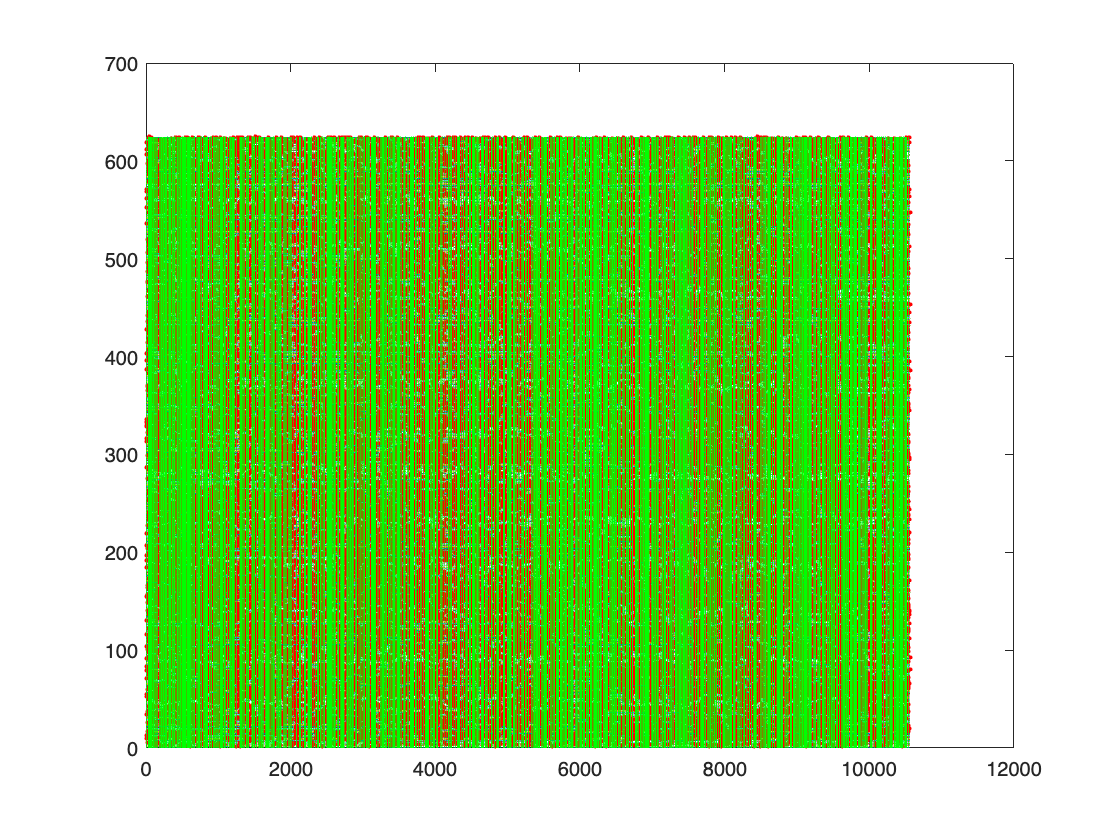


%Tr1b=double(allcells(iscell(:,1)>0,:));

%% preprocessing

%speedsm =smoothdata(speed,'gaussian',10);
Tr1b=Tr1b./median(Tr1b,2);
%Tr1b=readNPY('/Users/platel/Desktop/exp/sce.npy');
WinRest=find(speed<1);
% only use rest period
Tr1b = Tr1b(:,WinRest);

%bleaching correction

% Savitzky-Golay filter
Tr1b = sgolayfilt(Tr1b',3,5)';

%Tr1b = Tr1b(:,WinRest);
[NCell,Nz] = size(Tr1b);
MovT=transpose(1:Nz);  %put real time

%% Detect small calcium transients
% [NCell,Nz] = size(Tr1b);
% Tr1b = Tr1b(:,WinRest);
%TrRest = Tr1b;

figure
for i = 1:NCell
    plot(MovT,Tr1b(i,:)+i-1)
    hold on
end

% Detect Calcium Transients using a sliding window
%Tr1b = Tr1b(:,WinRest);
%TrRest = Tr1b;
Raster = zeros(NCell,Nz);
%WinSize = 40;
WinSize = round(4 * imaging_sampling_rate);

% Acttmp = zeros(1,Nz);
% Sigtmp = zeros(1,Nz);

%Acttmp2 = zeros(1,NCell);

parfor i=1:NCell    

    MinPeakDistance=5;
    th(i)=3*iqr(Tr1b(i,:));
    %th(i)=3*std(Tr1b(i,:));
    [~,Acttmp2{i}] = findpeaks(Tr1b(i,:),'MinPeakProminence',th(i),'MinPeakDistance',MinPeakDistance);
    %Acttmp2{i}=locs;%%%%%%%%findchangepts(y,MaxNumChanges=10,Statistic="rms")

end
%figure
for i = 1:NCell
    Raster(i,Acttmp2{i}) = 1;
        
    %plot(MovT,Tr1b(i,:)+i-1)
    %hold on
    plot(MovT(Acttmp2{i}),Tr1b(i,Acttmp2{i})+i-1,'.r')
end

% Sum activity over n (synchronous_frames ) consecutive frames

MAct = zeros(1,Nz-synchronous_frames);
for i=1:Nz-synchronous_frames
    MAct(i) = sum(max(Raster(:,i:i+synchronous_frames),[],2));
end

% Select synchronies (RACE)

[pks,TRace] = findpeaks(MAct,'MinPeakHeight',sce_n_cells_threshold,'MinPeakDistance',5);
% sumpeaks=sum(peaks)
NRace = length(TRace);

% Create RasterPlots
Race = zeros(NCell,NRace);
RasterRace = zeros(NCell,Nz);
for i = 1:NRace
    Race(:,i) = max(Raster(:,TRace(i)-1:TRace(i)+2),[],2);
    RasterRace(Race(:,i)==1,TRace(i)) = 1;
end

% Display race
for i = 1:length(TRace)
    line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
end

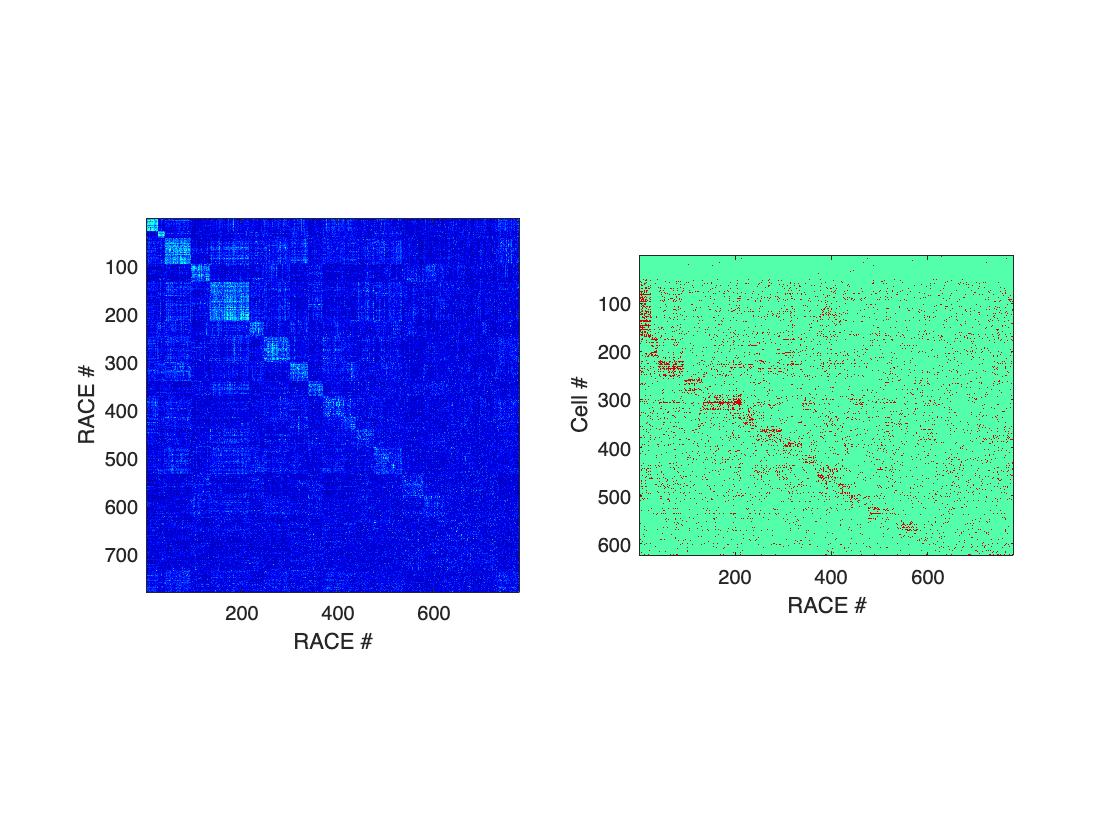

%toc
%return
% break
%% Save
save([PathSave,'Acttmp2.mat'],'Acttmp2')
save([PathSave,'Race.mat'],'Race')
save([PathSave,'TRace.mat'],'TRace')



%% Clustering
[NCell,NRace] = size(Race);
[IDX2,sCl,M,S] = kmeansopt(Race,100,'var');
% M = CovarM(Race);
% IDX2 = kmedoids(M,NCl);
NCl = max(IDX2);

[~,x2] = sort(IDX2);
MSort = M(x2,x2);

%Race clusters
R = cell(0);
CellScore = zeros(NCell,NCl);
CellScoreN = zeros(NCell,NCl);
for i = 1:NCl
    R{i} = find(IDX2==i);
    CellScore(:,i) = sum(Race(:,R{i}),2);
    CellScoreN(:,i) = CellScore(:,i)/length(R{i});
end
%Assign cells to cluster with which it most likely spikes
[~,CellCl] = max(CellScoreN,[],2);
%Remove cells with less than 2 spikes in a given cluster
CellCl(max(CellScore,[],2)<2) = 0;
[X1,x1] = sort(CellCl);

figure
subplot(1,2,1)
imagesc(MSort)
colormap jet
axis image
xlabel('RACE #')
ylabel('RACE #')

subplot(1,2,2)
imagesc(Race(x1,x2),[-1 1.2])
axis image
xlabel('RACE #')
ylabel('Cell #')


%% Save Clusters
save([PathSave,'Clusters.mat'],'IDX2')


%% Remove cluster non-statistically significant
tic
sClrnd = zeros(1,100);
for i = 1:20
    sClrnd(i) = kmeansoptrnd(Race,50,NCl);  %was at 10 but too variable from one time to the other
end
NClOK = sum(sCl>max(sClrnd));
sClOK = sCl(1:NClOK)';

save([PathSave,'NClustersOK.mat'],'NClOK')

RaceOK = Race(:,IDX2<=NClOK);
NRaceOK = size(RaceOK,2);
toc

Elapsed time is 128.978275 seconds.


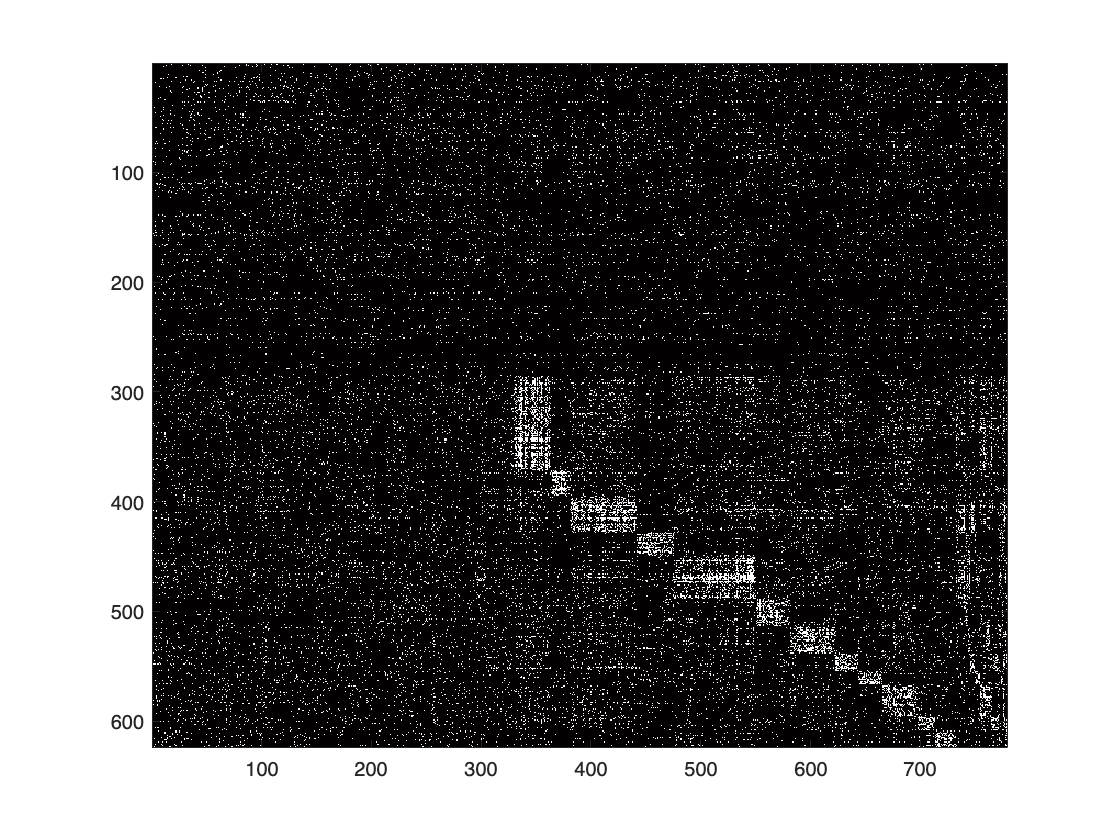

NCl = 12

Elapsed time is 158.458240 seconds.


pause (1)
RACE_Ortho

ncluster(sce_n_cells_threshold)=NCl;
%end